# %%updated 2025-04-17 by Ronan, E.A, and Wan, S.W. (Emrick Lab, University of Michigan)

# Initiation

%%This code is designed to process and analyze intensity traces from Excel data files.
% It normalizes these traces, computes average traces with standard error, and visualizes results using plots and graphs.
% The primary audience for this code includes researchers and data analysts working with fluorescence or other intensity-related data.


clear
clc
close all
set(0, ...
 'DefaultTextInterpreter', 'latex', ...
 'DefaultAxesTickLabelInterpreter', 'latex', ...
 'DefaultAxesFontSize', 12, ...
 'DefaultLegendInterpreter', 'latex', ...
 'DefaultLegendFontSize', 14, ...
 'DefaultTextboxshapeInterpreter', 'latex');

## Normalize Intensity Traces

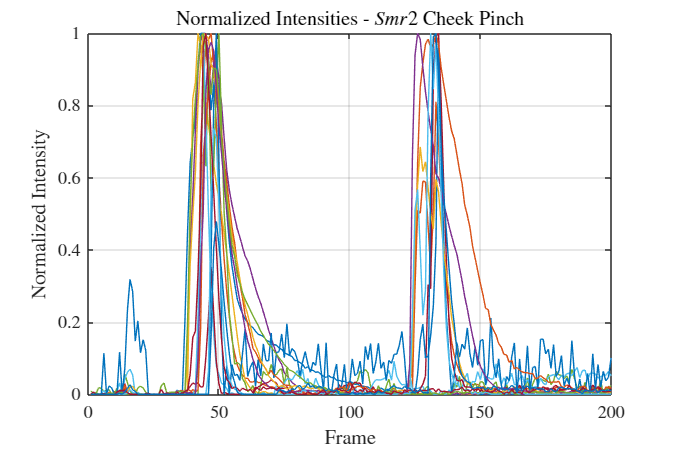

% The code reads intensity data from an Excel file and normalizes these traces.
% Normalization is performed through maximum intensity scaling.

[~,~,~,numericMatrix] = read_data(0);
norm_ints = normalization1(numericMatrix);
width = 600; height = 400;
screen_pix = get(0,'screensize');
figure('Position',...
       [(screen_pix(3)-width)/2,(screen_pix(4)-height)/2,width,height])
plot(norm_ints)
grid on
xlabel('Frame')
ylabel('Normalized Intensity')
title('Normalized Intensities - $Smr2$ Cheek Pinch')

## Averaged Normalized Intensity Trace & SE

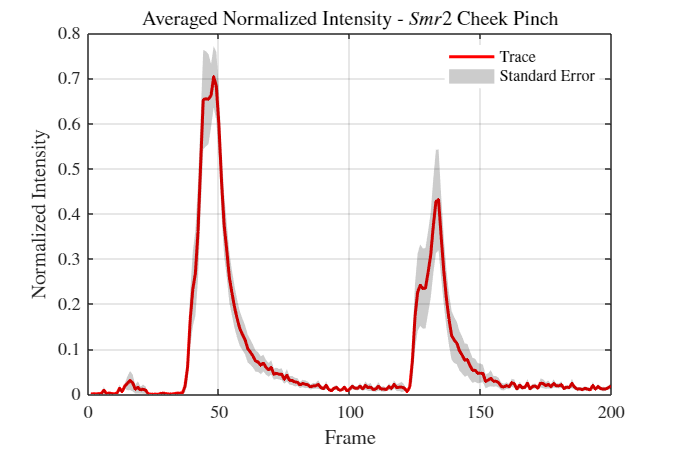

%Calculates the average trace and standard error from the normalized intensities.
%Plots these with shaded error bands.

avg_traces = mean(norm_ints,2);
sd = std(norm_ints,0,2);
se = sd/sqrt(size(norm_ints,2));
fill_trace = 1:size(norm_ints,1);
fill_trace = [fill_trace,fliplr(fill_trace)];
fill_inten = [(avg_traces+se)',fliplr((avg_traces-se)')];

figure('Position',...
       [(screen_pix(3)-width)/2,(screen_pix(4)-height)/2,width,height])
plot(avg_traces,'r','linewidth',2)
hold on
fill(fill_trace,fill_inten,'k','FaceAlpha',0.2,'EdgeAlpha',0)
hold off
grid on
xlabel('Frame')
ylabel('Normalized Intensity')
title('Averaged Normalized Intensity - $Smr2$ Cheek Pinch')
legend({'Trace','Standard Error'})
legend('boxoff')

## Area Under Normalized Intensity Traces (AUC)

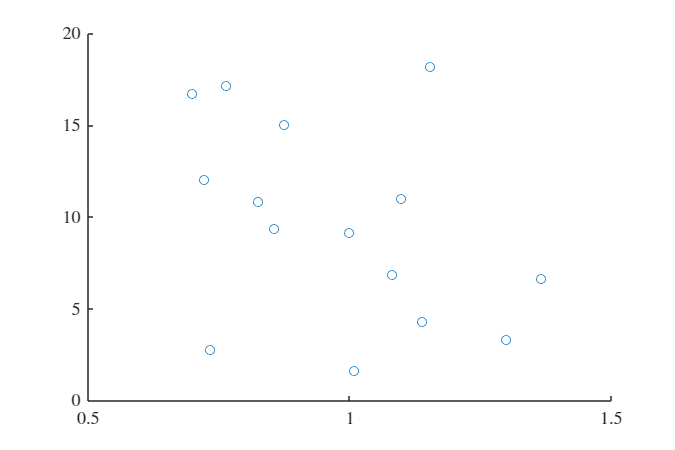

%% Define the window for Area Under the Curve (AUC) calculation
% Adjust these values to specify the range of frames over which to calculate the AUC.
% For example, setting window1 = [10, 50] calculates the AUC from frame 10 to frame 50.

window1 = [40,100];

% Calculate the Area Under the Curve (AUC) for normalized intensity traces within the specified window

AUC = trapz(norm_ints(window1(1):window1(2),:),1);

%Plot the results
x1 = ones(size(AUC));
swarmchart(x1,AUC)

## Peak Amplitude of Traces

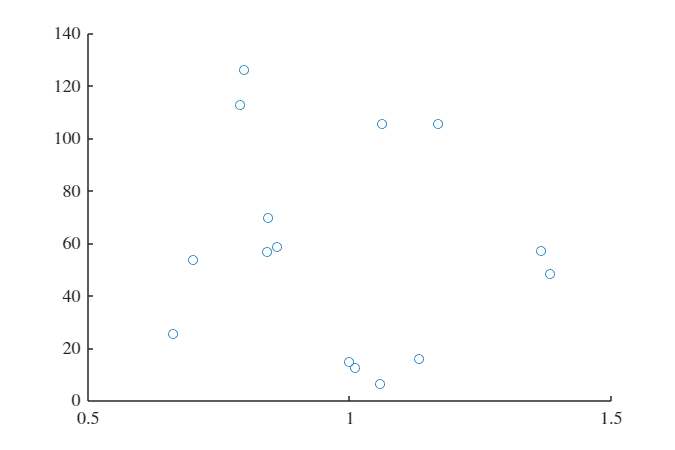

% Define the window for peak amplitude calculation
% Adjust these values to specify the range of frames to search for the maximum intensity.

% Example: Setting window2 = [20, 80] finds the peak intensity between frame 20 and frame 80.
window2 = [40,100];

% Calculate the peak amplitude of intensity traces within the specified window
MaxIntensity = max(numericMatrix(window2(1):window2(2),:),[],1);

%% Plot the results
x2 = ones(size(MaxIntensity));
swarmchart(x2,MaxIntensity)

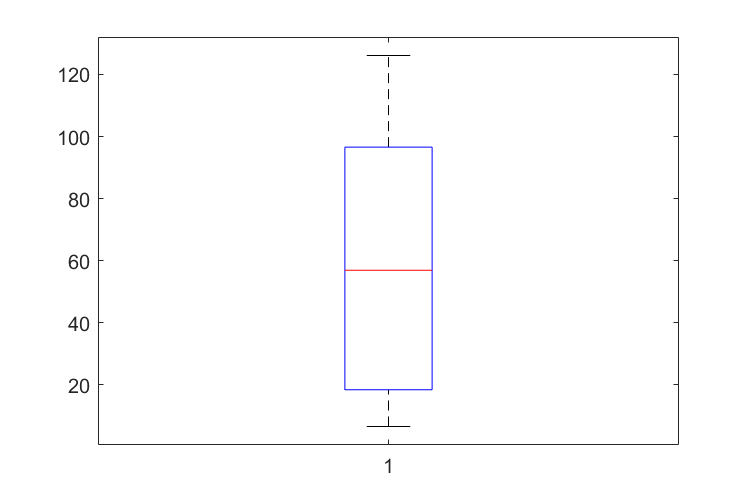

boxplot(MaxIntensity)

## Functions

function [file,path,rawData,numericMatrix] = read_data(skipcol1)
    rawData = []; numericMatrix = [];
    [file, path] = uigetfile({'*.xlsx;*.xls','Excel Files (*.xlsx, *.xls)'},'Select an Excel file');
    if isequal(file, 0) || isequal(path, 0)
        disp('User pressed cancel');
        return
    else
        excelFilePath = fullfile(path, file);
        [~, ~, ext] = fileparts(file);
        numericMatrix = [];
        switch lower(ext)
            case {'.xlsx', '.xls'}
                rawData = readtable(excelFilePath,'VariableNamingRule','preserve');
                try
                    numericMatrix = table2array(rawData);
                catch
                    disp('Non-numeric data encountered. Check your Excel file.');
                    numericMatrix = [];
                end           
            otherwise
                disp(['Unsupported file type: ', ext]);
        end
    end
    if skipcol1
        numericMatrix = numericMatrix(:,2:end);
    end
    % remove empty columns
    [numericMatrix,~] = rmmissing(numericMatrix,2,'MinNumMissing',height(numericMatrix));
end

function norm_ints = normalization1(numericMatrix)
    max_int = max(numericMatrix,[],1);
    norm_ints = numericMatrix./max_int;
    norm_ints(norm_ints<0) = 0; % set negative intensities to 0
end

function norm_ints = normalization2(numericMatrix)
    max_int = max(numericMatrix,[],1);
    min_int = min(numericMatrix,[],1);
    scales = max_int-min_int;
    shifted_ints = numericMatrix-repmat(min_int,[size(numericMatrix,1),1]);
    norm_ints = shifted_ints./scales;   
end